%Start
clear; clc; format long
tic

# Traffic Data Analysis for Modelling and Prediction of Traffic Scenario

####  Girolamo Oddo

***Work carried out in relation to the "Mathworks Innovation Excellence" initiative***

[*MathWorks Site*](https://it.mathworks.com/academia/matlab-engineering-project-ideas.html)* | *[*Project-specific Mathworks repository*](https://github.com/mathworks/MathWorks-Excellence-in-Innovation/tree/main/projects/Traffic%20Data%20Analysis%20for%20Modelling%20and%20Prediction%20of%20Traffic%20Scenarios)

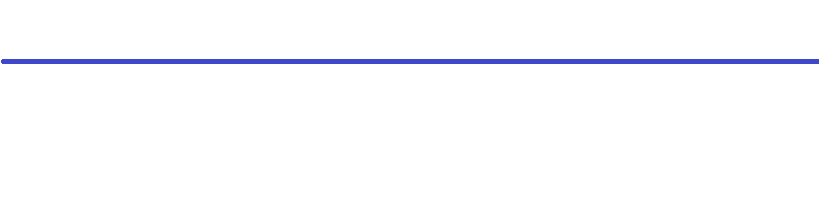

## **Use this code to get predictions from the pretrained net**

**1. Loads the already trained Network "NARXnet_TRAINED.mat", the X Inputs "X-Input.xlsx" and Y Feed-Backs "Y-FeedBack.csv"**

As the network is constituted, in order to perform the prediction it is necessary to have the feedback value n-1 available.

In this example case a small set of 27 rows has been loaded where in fact only the last value will be predicted, the feedback element n has been loaded equal to 0,0,0,0,0,0,0, i.e. the null element.

This has been done because even if the n element does not participate in the prediction it is necessary to guarantee the dimensional congruence between the two vectors.

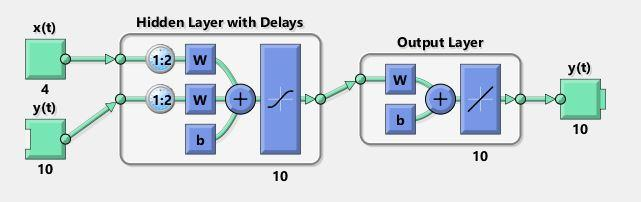

*Extract from the code:*


%Load Net, Input X end FeedBack Y 

%Net
load NARXnet_TRAINED.mat

%In X
IN = readmatrix('X-Input.xlsx');
X = tonndata(IN,false,false);

%FB Y
TARG = readmatrix('Y-FeedBack.csv');
T = tonndata(TARG,false,false);



** 2. Prepare input and target time series data for network simulation or training**

*Extract from the code:*

[More about preparets function](https://it.mathworks.com/help/deeplearning/ref/preparets.html)


%Preparation recalling Net name,Input X, Feedback Y
[x,xi,ai,~] = preparets(NARXnet_TRAINED,X,{},T);



**3. Perform the prediction**

*Extract from the code:*


%Prediction 
newoutput = NARXnet_TRAINED(x,xi,ai);


**4. Prepares the output to be converted from binary to string form for better readability of the result**

*Extract from the code:*


%Output preparation to pass from Binary to Categorical
newoutput = cell2mat(newoutput);
newoutput = round(newoutput,0);
newoutput = num2cell(newoutput);
newoutput = newoutput';

%Reference vector to trasform Bin2Categorical
REF=["1;0;0;0;0;0;0;0;0;0";"0;1;0;0;0;0;0;0;0;0";"0;0;1;0;0;0;0;0;0;0";"0;0;0;1;0;0;0;0;0;0";"0;0;0;0;1;0;0;0;0;0";...
    "0;0;0;0;0;1;0;0;0;0";"0;0;0;0;0;0;1;0;0;0";"0;0;0;0;0;0;0;1;0;0";"0;0;0;0;0;0;0;0;0;1"];



**5. Perform the conversion**

According to the following table the results obtained from the network will be converted:

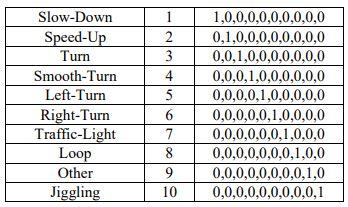

*Extract from the code:*


[m,~] = size(newoutput);

%Initialization of "Results" Array 
results=cell(m,1);    

%Trasformation cycle to pass from Bin to Categorical
for j=1:m
       
    %Aux Variables
    A1=string(newoutput{j,1});
    A2=string(newoutput{j,2});
    A3=string(newoutput{j,3});
    A4=string(newoutput{j,4});
    A5=string(newoutput{j,5});
    A6=string(newoutput{j,6});
    A7=string(newoutput{j,7});
    A8=string(newoutput{j,8});
    A9=string(newoutput{j,9});
   
    
    if     strcmp(A1,"1")==1
           results{j} = 'Slow-Down';
        
    elseif strcmp(A2,"1")==1
           results{j} = 'Speed-Up'; 
        
    elseif strcmp(A3,"1")==1
           results{j} = 'Turn';
           
    elseif strcmp(A4,"1")==1       
           results{j} = 'Smooth-Turn';
           
    elseif strcmp(A5,"1")==1
           results{j} = 'Left-Turn';
           
    elseif strcmp(A6,"1")==1      
           results{j} = 'Right-Turn';
            
    elseif strcmp(A7,"1")==1  
           results{j} = 'Traffic-Light';
           
    elseif strcmp(A8,"1")==1 
           results{j} = 'Loop';
    
    elseif strcmp(A9,"1")==1
           results{j} = 'Jiggling';
    
    else 
           results{j} = 'Other';       
           
    end 
end


**6. Explore results**

toc   

Elapsed time is 15.166501 seconds.


fprintf('PREDICTIONS \n')

PREDICTIONS 


disp(results) 

    {'Jiggling' }
    {'Jiggling' }
    {'Slow-Down'}
    {'Slow-Down'}
    {'Slow-Down'}
    {'Slow-Down'}
    {'Slow-Down'}
    {'Slow-Down'}
    {'Slow-Down'}
    {'Slow-Down'}
    {'Slow-Down'}
    {'Slow-Down'}
    {'Slow-Down'}
    {'Slow-Down'}
    {'Slow-Down'}
    {'Slow-Down'}
    {'Slow-Down'}
    {'Slow-Down'}
    {'Slow-Down'}
    {'Speed-Up' }
    {'Speed-Up' }
    {'Speed-Up' }
    {'Speed-Up' }
    {'Speed-Up' }
    {'Speed-Up' }

